player module that uses the audioplayer object  

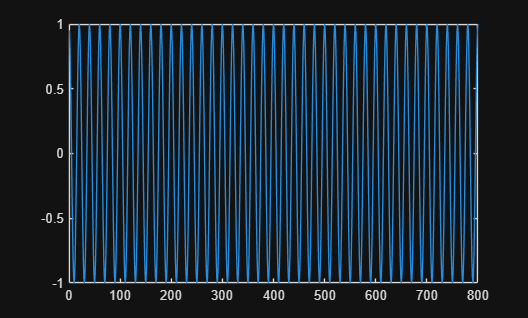

% read some parameters for generating the audio
fields = (load("data.mat"));


tau0 = fields.tau0;
tau1 = fields.tau1;
tauS = fields.tauS;

f0 = 1/tau0;
f1 = 1/tau1;

% number of bits in test signal
n=10;

% generate a test sin wave
x = [1:1:tauS*n];
test = cos(2*pi*f0 * x); 

plot(x, test)

find the correct output audio device

outDevices = audiodevinfo().output

outDevices = 1×3 struct array with fields:
    Name
    DriverVersion
    ID



% the device name is 'Speaker (Realtek(R) Audio) (Windows DirectSound)'
speakerName = 'Headphone (Realtek(R) Audio) (Windows DirectSound)';
speakerID = 0;

% lets find the corresponding ID
for idx = [1:1:audiodevinfo(0)]
    if strcmp(outDevices(idx).Name, speakerName)
        speakerID = outDevices(idx).ID;
    end
end
speakerID

speakerID = 3

prepare the audioplayer object

% use default sample rate of audiorecorder object (8000)
Fs = 8000;
nBits = 8;
player = audioplayer(test, Fs, nBits, speakerID)

player =   audioplayer with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: 3
    CurrentSample: 1
     TotalSamples: 800
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


now use object functions to play the associated signal

playblocking(player)